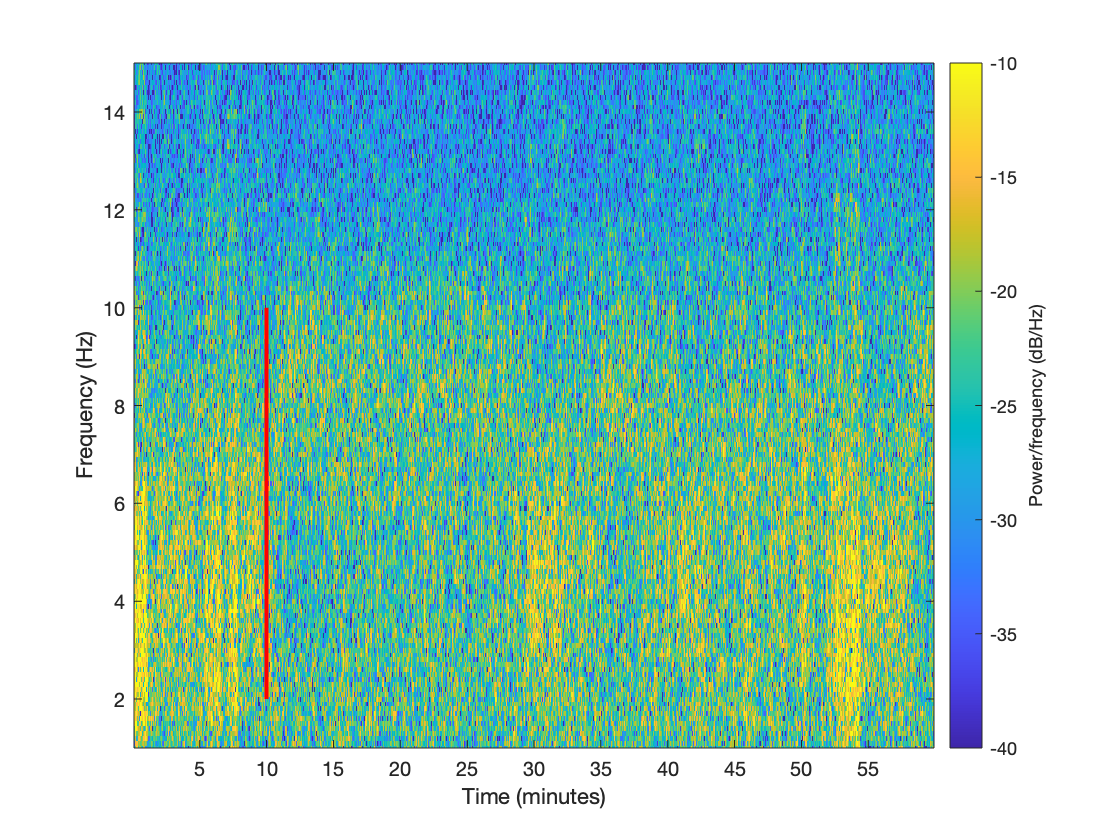

data=readNPY('downsampEEG_Acq14.npy');

Fs = 200; % 

tWindow = 10; % 
NWindow = Fs*tWindow; % 
window = hamming(NWindow); % Window used in the spectrogram

NFFT = NWindow;
NOverlap = NWindow*0.99; % We want a 99% overlap, 

% [S, F, T, ps] = 
figure
spectrogram(data, window, NOverlap, NFFT, Fs,'yaxis');
ylim([1,15])
% set(gca,'ColorScale','log')
caxis([-40 -10])
hold on
line([10 10],[10 2],'LineWidth',2,'Color','Red')

vidobj=VideoWriter('mymovie2','MPEG-4');
vidobj.FrameRate=1;
open(vidobj);

for i=1:3600
    f=figure;
    f.Position=[10 10 1100 300];
    spectrogram(data, window, NOverlap, NFFT, Fs,'yaxis');
    ylim([1,15])
    caxis([-40 -10])
    hold on
    line([i*(1/60) i*(1/60)],[15 1],'LineWidth',2,'Color','Red')
    hold off
    
    currFrame = getframe;
    writeVideo(vidobj,currFrame);
    
    delete(f)
end


close(vidobj);
